# EXTRACT -  A Quick Start

This tutorial provides example code to get a newcomer started with EXTRACT.

Written by Fatih Dinc, 03/25/2024

## Load data

This example file contains a movie M, ground truth cell maps (S_ground) and traces (T_ground)

clear
clc
load('example.mat');

## Watch the movie

The parameter 'pause_time' determines the speed of the movie. For example, for the movie below, between each frame, Matlab pauses for 0.01s.

%view_movie(M(:,:,1:500),'pause_time',0.01)

## Initialize configuration parameters

### **Essential parameters**

Without these essential parameters, EXTRACT will give an error.

config = get_defaults([]); %calls the defaults
config.avg_cell_radius=7; 

### **Optional parameters**

%Movie is small enough that EXTRACT will not automatically partition this,
%but still a good idea to keep these in sight!
config.num_partitions_x=1;
config.num_partitions_y=1; 
config.use_gpu=0; % This is a small dataset, will be fast on cpu anyways.
config.trace_output_option='no_constraint'; 
config.cellfind_max_steps =20; % There are 20 cells in this movie
config.visualize_cellfinding=1; % Let's watch EXTRACT find these cells. Normally, off!
config.thresholds.T_min_snr = 10; % change this parameter to see cells being rejected

## Run EXTRACT

Perform the actual extraction

26-Mar-2024 00:57:44: Signal extraction will run on 1 partitions serially... 
26-Mar-2024 00:57:44: Signal extraction on partition 1 (of 1):
	 	 	 Uploading the movie... 
	 	 	 Upload finished in 0.0 minutes ... 
	 	 	 Preprocessing movie...
	 	 	 Finding cells with component-wise EXTRACT...
	 	 	 Using cell finding visualization tool...
	 	 	 	 noise std: 0.0065 
	 	 	 	 minimum magnitude: 0.0090 


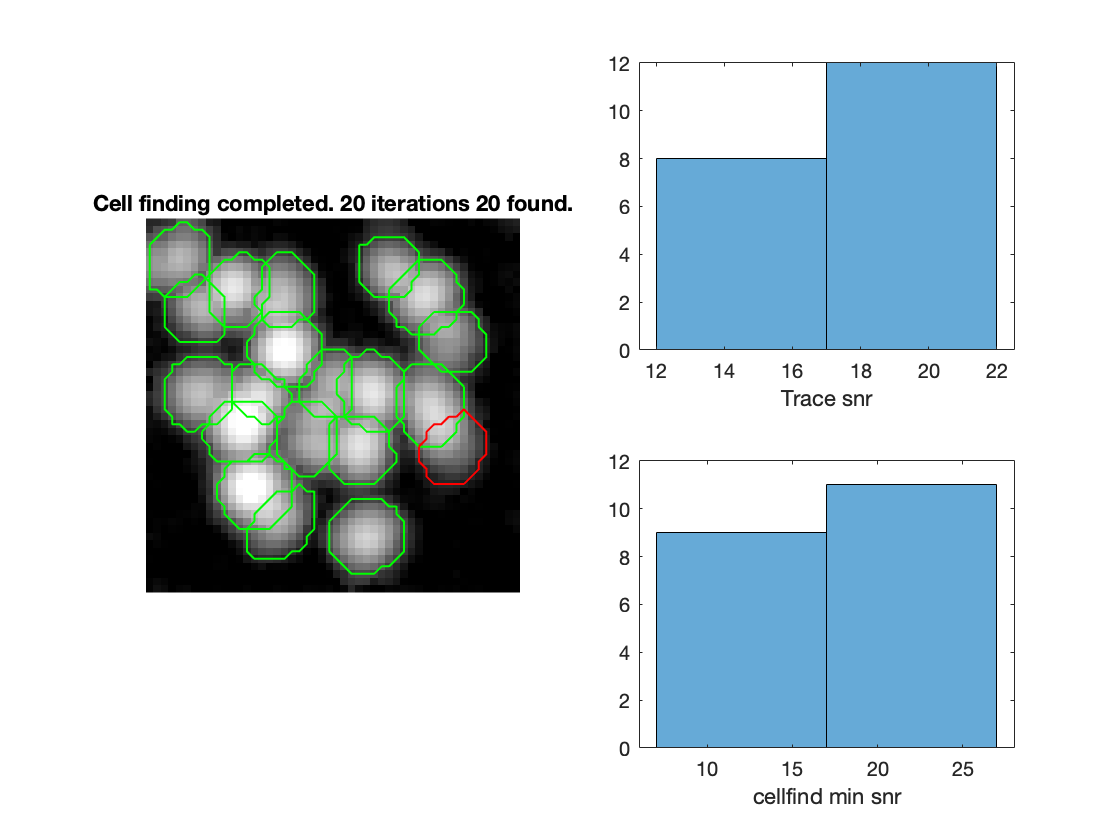

	 	 	 20 cells found after a total of 20 steps... 
	 	 	 Updating S and T with alternating estimation...
	 	 	 End of iter # 1: # cells: 20 (0 removed) 
	 	 	 End of iter # 2: # cells: 20 (0 removed) 
	 	 	 End of iter # 3: # cells: 20 (0 removed) 
	 	 	 End of iter # 4: # cells: 20 (0 removed) 
	 	 	 End of iter # 5: # cells: 20 (0 removed) 
	 	 	 End of iter # 6: # cells: 20 (0 removed) 
	 	 	 Providing traces with robust regression and no non-negativity constraint... 
	 	 	 Count: 20 cells.
26-Mar-2024 00:57:58: Total of 20 cells are found.
26-Mar-2024 00:57:58: Removing duplicate cells...
26-Mar-2024 00:57:58: 20 cells were retained after removing duplicates.
26-Mar-2024 00:57:58: All done with EXTRACT! 


%% Perform EXTRACTion:
output=extractor(M,config);

## Match the EXTRACT outputs to the ground truth

%% Matching ground truth to EXTRACTed signals
[h,w,k]=size(full(output.spatial_weights));
S_ex=reshape(full(output.spatial_weights),h*w,k);
idx_match = match_sets(S_ground, S_ex); %this is a very useful helper function, use this as you need!
T_ex = output.temporal_weights';

## Compute the signals averaged inside the ROIs

%% Compute the ROI signals
M_res=reshape(M,2500,2000);
X=mean(M_res,2);
M_res=(M_res-X)./X; %perform dfof
T_roi=pinv(diag(diag(S'*S)))*S'*M_res;
T_roi = T_roi - quantile(T_roi,.25,2);

## Evaluate performance

Examine relative to ground truth

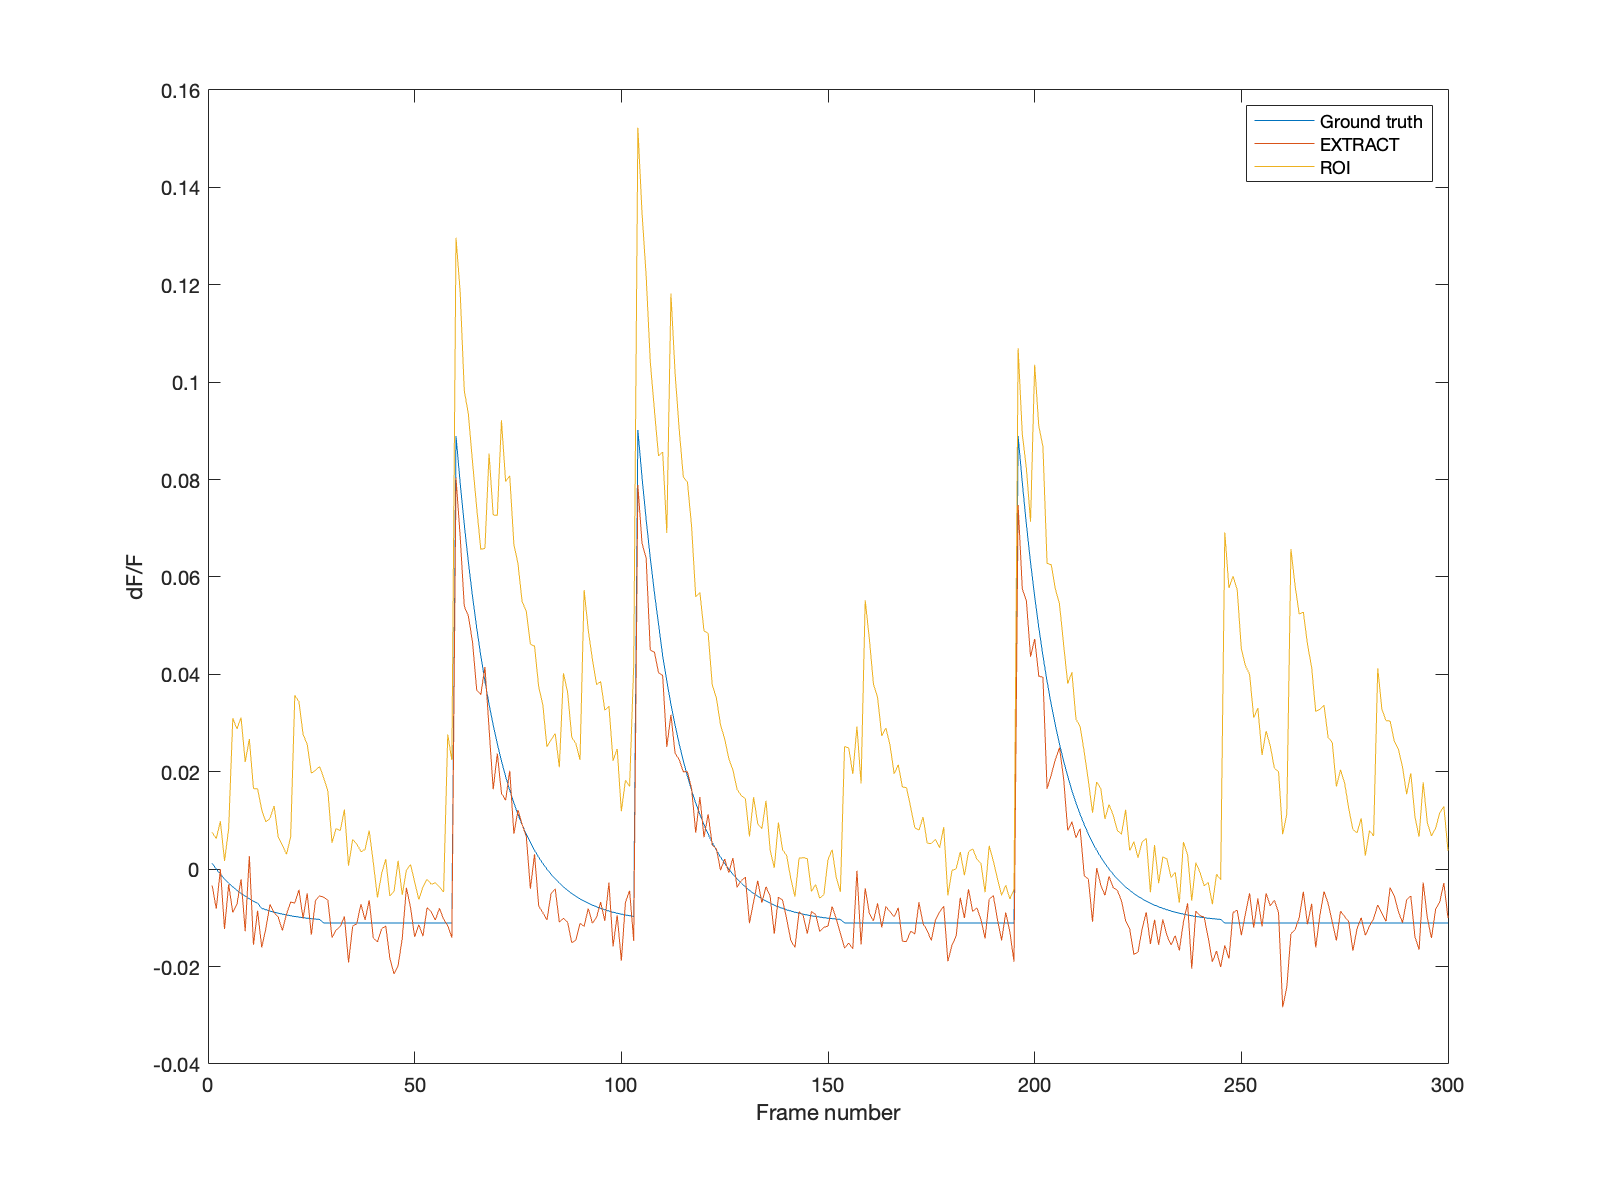

%% Plot the results
fig = figure(); 
fig.Position(3:4) = [2000, 1100];
pick=14;
plot(T_ground(idx_match(1,pick),301:600))
hold on
plot(T_ex(idx_match(2,pick),301:600));
hold on
plot(T_roi(idx_match(2,pick),301:600))
legend('Ground truth','EXTRACT','ROI')
ylabel('dF/F');
xlabel('Frame number')

## Plotting the cells' spatial profiles

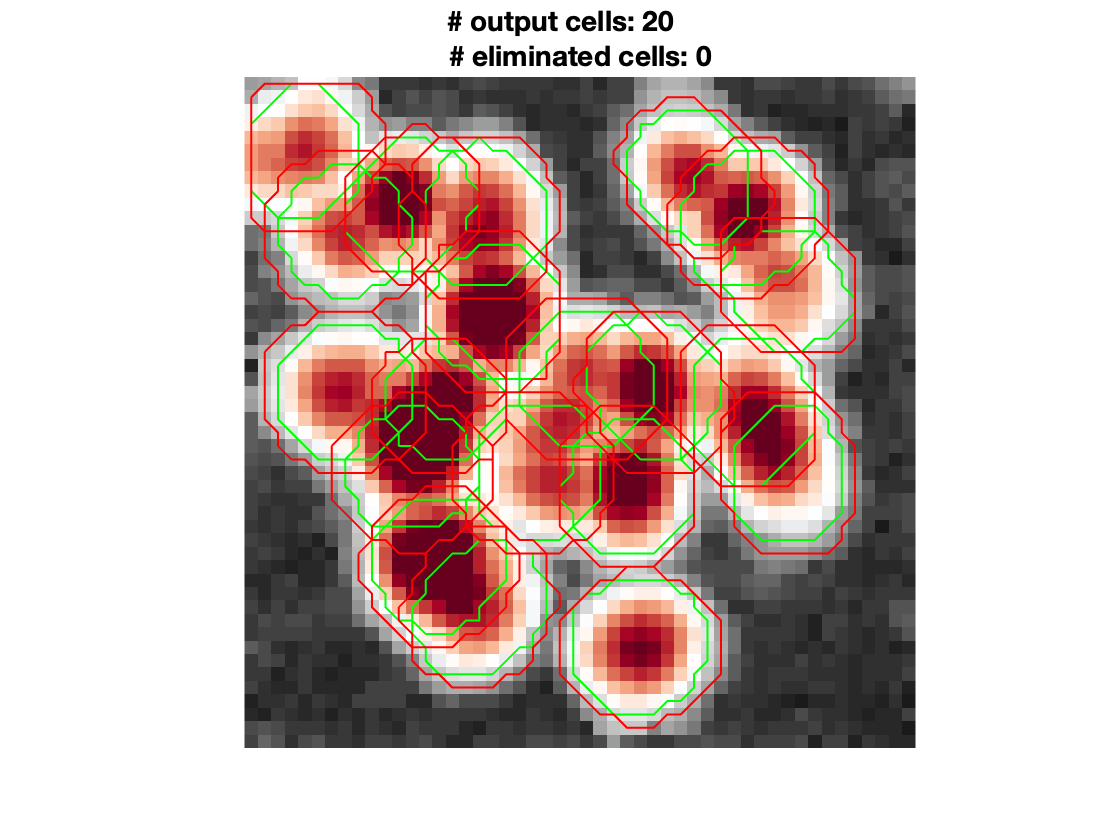

figure
plot_output_cellmap(output)
plot_cells_overlay(reshape(S_ground,50,50,[]),[1,0,0]) % ground truth will be in red